# Parallel Simulation with parsim

Parallel Simulink simulations have been simplified with the [`parsim`](https://www.mathworks.com/help/simulink/slref/parsim.html) commmand. This example does the same thing as the `parfor` loop utilizing `parsim` instead.

This is a simple example without more advanced pieces like model reference or StateFlow or anything else where a compilation step is necessary. `parsim` will take care of this if running the simulation on a cluster.

## Set up

clear variables

## Damping and stiffness

We are going to parameter sweep over different combinations of damping and stiffness. Define a grid of all combinations.

bNum = 5;
kNum = 5;
bVals = linspace(0.1, 5, bNum);  % damping values
kVals = linspace(1.5, 5, kNum);  % stiffness values
[kGrid, bGrid] = meshgrid(bVals, kVals);

## Set up simulation

Set up the [`Simulink.SimulationInput`](https://www.mathworks.com/help/simulink/slref/simulink.simulationinput-class.html) object for each unique simulation.  Here we will set the variables that are changing for each iteration.  

**Note:** The loop is running backwards to dynamically preallocate the data type.

for idx = numel(kGrid):-1:1
    in(idx) = Simulink.SimulationInput('DampedOscillator');
    in(idx) = in(idx).setVariable('R',bGrid(idx));
    in(idx) = in(idx).setVariable('D',kGrid(idx));
end

These variables are shared across all models.

in = in.setVariable('x0',0);
in = in.setVariable('x0_dot',1);
in = in.setVariable('m',5)

in =   1×25 SimulationInput array with properties:

    ModelName
    InitialState
    ExternalInput
    ModelParameters
    BlockParameters
    Variables
    PreSimFcn
    PostSimFcn
    UserString


## Simulate in parallel

Call `parsim`; we will have it update progress and use Fast Restart.

out = parsim(in, 'ShowProgress', true, 'UseFastRestart', true,'ShowSimulationManager','on')

[13-Sep-2022 08:51:18] Checking for availability of parallel pool...
Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 4).
[13-Sep-2022 08:51:42] Starting Simulink on parallel workers...
[13-Sep-2022 08:51:50] Configuring simulation cache folder on parallel workers...
[13-Sep-2022 08:51:51] Loading model on parallel workers...
[13-Sep-2022 08:51:55] Running simulations...
[13-Sep-2022 08:52:03] Cleaning up parallel workers...


out = 1x25 Simulink.SimulationOutput array



## Unpack output

Each simulation returns a full `SimulationOutput` object. Unpack these and take the maximum value of each simulation.

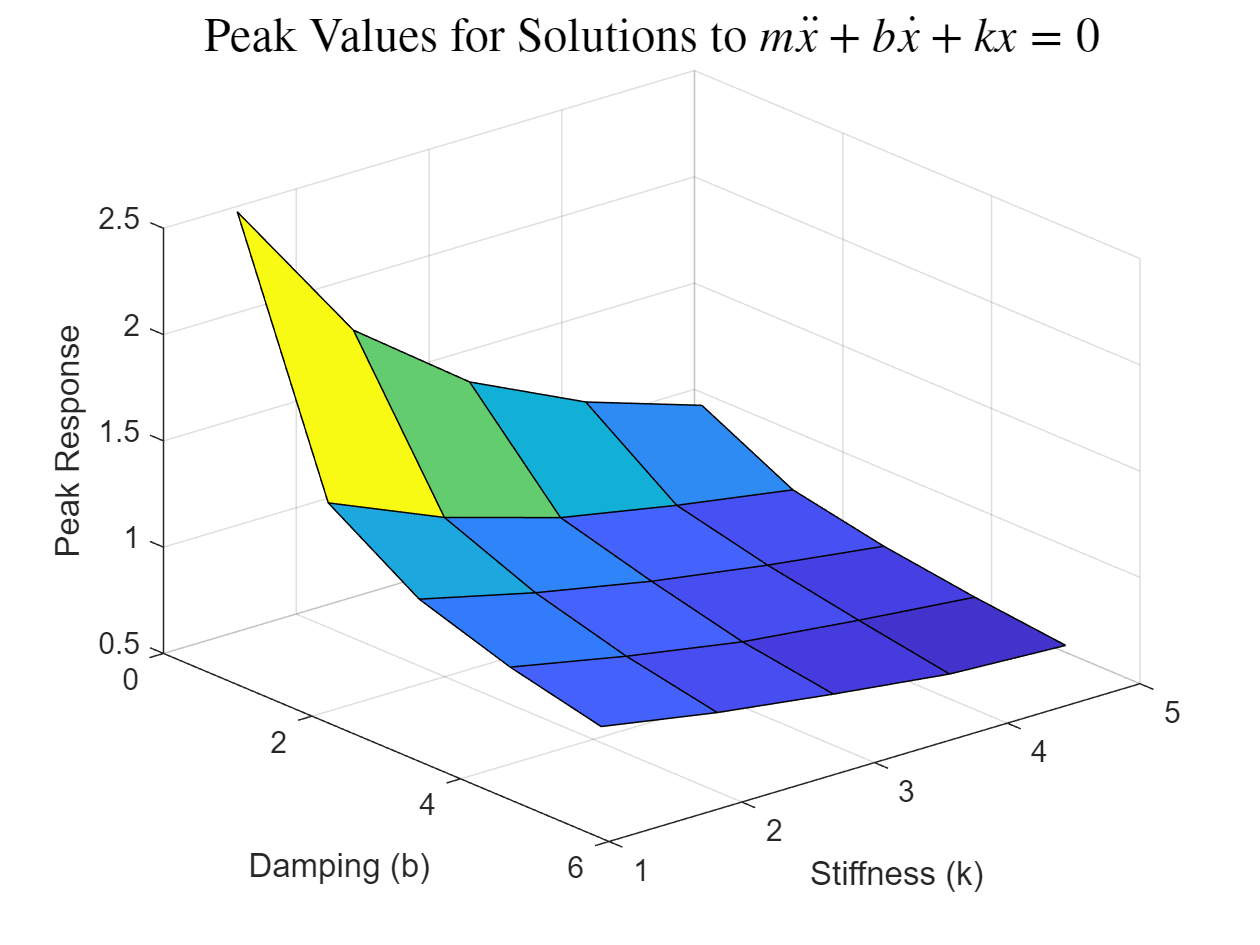

[youtcell{1:numel(kGrid)}] = out(:).yout;
peakVals = reshape(cellfun(@max, youtcell), size(kGrid));
visualizeParamSweep(bVals, kVals, peakVals)

## Simulate in batch using `batchsim`

You can also offload your simulation using [`batchsim`](https://www.mathworks.com/help/simulink/slref/batchsim.html).

delete(gcp('nocreate'))
numWorkers = 3;
job = batchsim(in,'Pool', numWorkers);

## Fetch outputs

The batch job runs asynchronously.  However, since we need the results to continue, we'll wait for it to finish and then fetch the outputs.

wait(job)
jobresults = fetchOutputs(job);
[youtcell{1:numel(kGrid)}] = jobresults(:).yout;
peakVals = reshape(cellfun(@max, youtcell), size(kGrid));
visualizeParamSweep(bVals, kVals, peakVals)

## Local function

function visualizeParamSweep(bVals, kVals, peakVals)

ax = gca;
surf(ax, bVals, kVals, peakVals)
xlabel(ax,'Damping (b)')
ylabel(ax,'Stiffness (k)')
zlabel(ax,'Peak Response')
title('Peak Values for Solutions to $m\ddot{x} + b\dot{x} + kx = 0$', ...
    'Interpreter', 'latex', 'FontSize', 16, 'FontWeight', 'Bold')
view(ax, 50, 30)

end

*Copyright 2020 The MathWorks, Inc.*